# 本代码目的是对实验对旋转管道声源进行定位测试

The following is an example of how to create an interactive narrative in the Live Editor. An interactive narrative ties together the computations that you use to solve a problem. This example shows how to:

- 验证管道声传播代码

- 验证基于频率对波束形成算法

- 将两者结合

- 对实验对静止声源进行验证

- 对实验对运动声源进行验证

## 实验说明

本试验在半消声室内进行，试验装置如下图所示。传声器齐平安装于管道壁面上，以声源所在位置为中心，传声器的位置详见mic_loc.mat。采样频率为16384Hz, 采样时间为50s（建议使用后30s）。

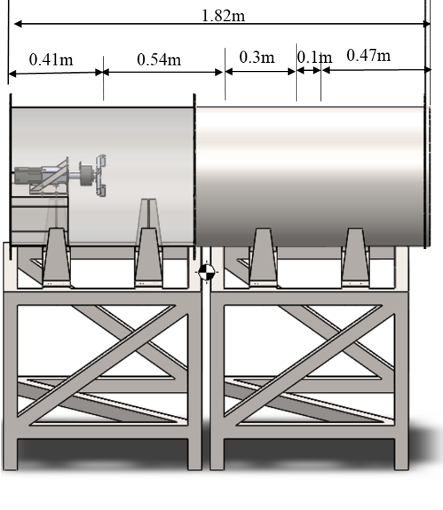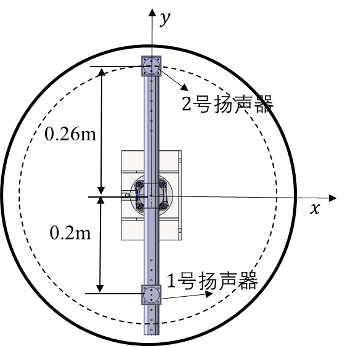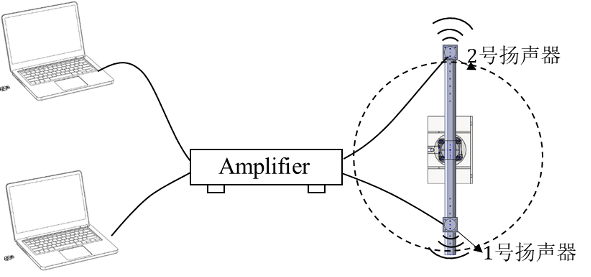

- **半无限长，一端开口带障板，另一端吸声**

- **半无限长，一端开口无障板，另一端吸声**

- **无线上，两端吸声，****14cm****厚度吸声棉**

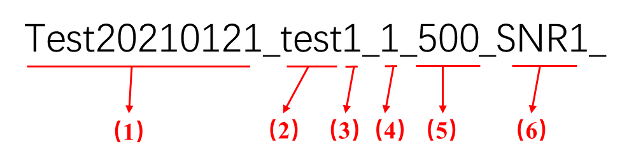

- 测试时间

- test——静止声源

- move——运动声源

- 1——一端开口带障板，另一端吸声

- 2——一端开口无障板，另一端吸声

- 3——两端吸声

- 1——1号扬声器工作

- 2——2号扬声器工作

- 12——1号和2号扬声器同时工作

- 500~6000——谐波噪声，频率Hz

- whitenoise——白噪声

- 信噪比，默认为不加噪声

- SNR1,SNR2,SNR3,在管道外播放白噪声，通过调节功放输出强度，模拟不同信噪比条件，SNR1>SNR2>SNR3,具体信噪比可根据信号计算得到。

文件名后还有1_1或1_2为数据导出过程中自动生成的，不代表任何意义。

%%----------------------Pwer by SJTU. CopyLicense------------------------%%
%%修复软壁面边界条件bug,2018-10-7,wjq                                     
%%add Logarithmic entropy condtion,2018-10-9,wjq                         
%%numerical green's function calculation,2018-10-10,wjq                  
%%colour plot of  Green’s function Pw,2018-10-12,wjq                    
%%mode bar  at a particular frequency ,2018-10-13,wjq                    
%%备注：均无量纲化处理；适用于Mx随r变化剪切流                              
%%推导GreenFunction                                                      
%%并行计算    
%生成单极子或者偶极子静止向管道传播动画
%%----------------------Pwer by SJTU. CopyLicense------------------------%%
clc;clear;close all
addpath(genpath(pwd));
warning('off')
% % //======保存图像至指定文件夹=============== // 
save_directory = ['./','结果输出/','声场模态输出',date];  %存储文件夹
if ~exist(save_directory) mkdir(save_directory);else disp('文件夹存在！');end

文件夹存在！


## 管道声传播代码---1. 求旋流管道特征值

给定仿真的频率，其传声器的发声频率

frequency = 1000;                              % 声源频率
rT = 0.185;   % 管道物理直径

%% 周向管道模态的范围
mode=[-40:40];
%% 径向模态的数目
n_len=7;
%% r坐标的配置点数
N =21;
%% 管道的半径
Ratio=0.6; 
%% cheb点选择，以及D为derivated function
[D,r] = cheb(N,Ratio,1); 
%% 周向马赫数
Mx=0.5*ones(N+1,1);%
%Mx=0.9-r.^2*0.9;%Figure11 (b)
%% 声速
c = 343; 

频率对应物理频率

w=frequency*2*pi*rT/c

w = 3.3889

w=25;

Entropy=0;Boundary=[1]; Type={'Hard Wall';'Lined Outer Wall';'Lined Inner Wall';'Lined Outer&Inner Wall'};
z_t=1-2*sqrt(-1);z_h=1-2*sqrt(-1);beta=[0.3]; 
Tr=0.0;Omag=0.0;
M_theta=Tr./r+Omag*r; %当旋流系数过大，则必须计算其影响;Mx不能为0
[c02,rou0,P0,s0]=entropyPara(r,N,Ratio,Omag,Tr,Entropy,beta);  
for wk=1:length(w)  
    for nk=1:length(mode)
    [V{wk,nk},lam{wk,nk}]=eigfun_AB(r,D,N,w(wk),mode(nk),Ratio,Mx,M_theta,rou0,P0,c02,Boundary,z_t,z_h);%求特征
    crLayer=[min((w(wk)-mode(nk)*M_theta./r)./Mx);max((w(wk)-mode(nk)*M_theta./r)./Mx)];
    cutOffLine=GMM_Cluster3(lam{wk,nk},crLayer); 
    [mode1{wk,nk},len1{wk,nk}]=eig_choose_nmax(V{wk,nk},N,r,Ratio,lam{wk,nk},w(wk),Mx,Tr,Omag,-1,10100,-1,500,crLayer,cutOffLine,n_len,0); %选特征    
    disp(['m=',num2str(mode(nk)),'  w=',num2str(w(wk)),'  upstram/downstream   mode:  ',num2str(len1{wk,nk}),' kx:  ',num2str(lam{wk,nk}(mode1{wk,nk}).')]);

    end
end

m=-40  w=25  upstram/downstream   mode:   kx:  
m=-39  w=25  upstram/downstream   mode:   kx:  
m=-38  w=25  upstram/downstream   mode:   kx:  
m=-37  w=25  upstram/downstream   mode:   kx:  
m=-36  w=25  upstram/downstream   mode:   kx:  
m=-35  w=25  upstram/downstream   mode:   kx:  
m=-34  w=25  upstram/downstream   mode:   kx:  
m=-33  w=25  upstram/downstream   mode:   kx:  
m=-32  w=25  upstram/downstream   mode:   kx:  
m=-31  w=25  upstram/downstream   mode:   kx:  
m=-30  w=25  upstram/downstream   mode:   kx:  
m=-29  w=25  upstram/downstream   mode:  0  0 kx:  -16.6667-14.5743i          -16.6667+14.5743i
m=-28  w=25  upstram/downstream   mode:  0  0 kx:  -16.6667-11.2869i          -16.6667+11.2869i
m=-27  w=25  upstram/downstream   mode:  0  0 kx:  -16.6667-6.7192i           -16.6667+6.7192i
m=-26  w=25  upstram/downstream   mode:  0  0 kx:  -22.5258-1.25899e-12i      -10.8076+2.14362e-12i
m=-25  w=25  upstram/downstream   mode:  0  0 kx:  -27.2039-3.5576e-12i      -6.12943

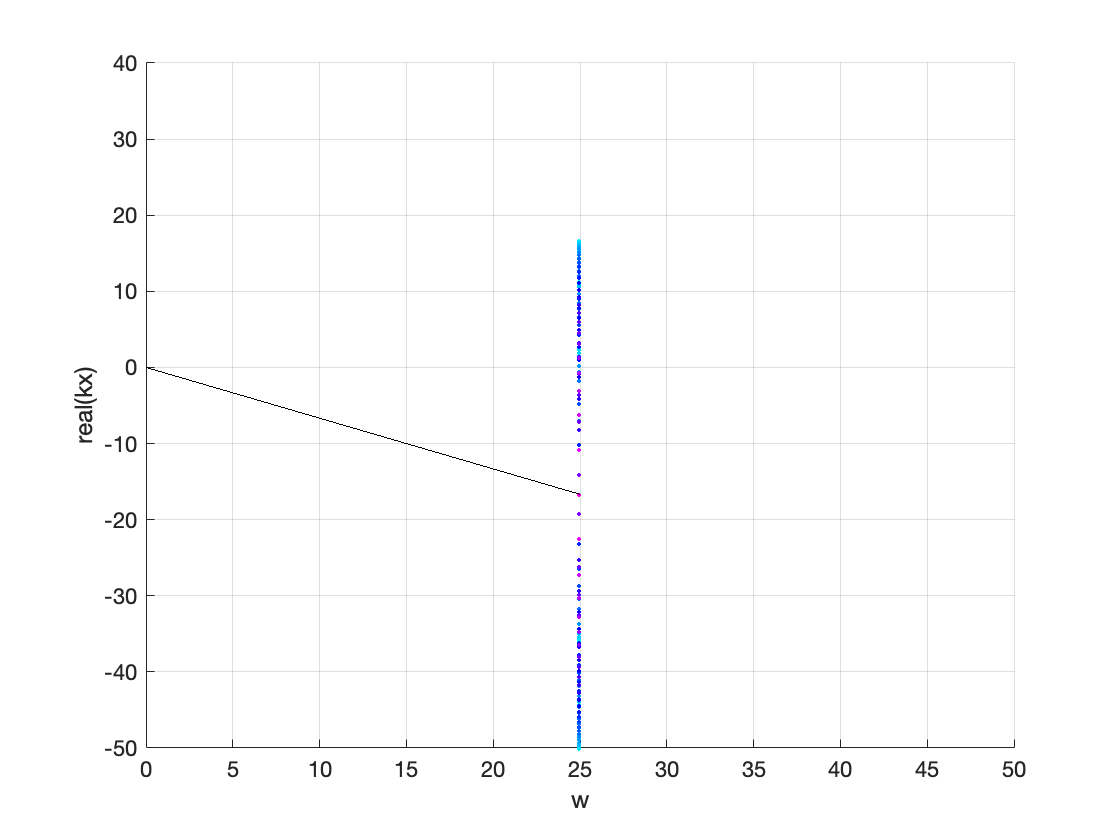

%% 调试代码段
fig = figure;
%subplot(1,2,1);
%title(['m=',num2str(mode)])
color1=hsv(length(mode));
for nk=1:length(mode)
for wk=1:length(w)
    %for mk=0:n_len
    %弄成三维的
    initialEigValue{wk,nk}=lam{wk,nk}(mode1{wk,nk});
    mode_enlarge{wk,nk}=mode(nk)*ones(size(lam{wk,nk}(mode1{wk,nk})));
    plot3(repmat(w(wk),length(mode1{wk,nk}),1),real(lam{wk,nk}(mode1{wk,nk})),repmat(mode(nk),length(mode1{wk,nk}),1),'.','Color',color1(nk,:));hold on;
    %plot3(repmat(w(wk),length(mode2{wk,nk}),1),real(lam{wk,nk}(mode2{wk,nk})),repmat(mode(nk),length(mode2{wk,nk}),1),'.','Color',color1(nk,:)); 
    %end
end
end 
hold on;
X = [0 0 w(end)  w(end);];
Y = [0 0 (-w(wk)*mean(Mx)./(1-mean(Mx).^2)) (-w(wk)*mean(Mx)./(1-mean(Mx).^2)); ];
Z = [mode(1) mode(end) mode(end)  mode(1); ];
para.TPP=fill3(X,Y,Z,'g','FaceAlpha',0.5); %添加颜色        % handle !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
set(para.TPP,'Visible','on')  
xlim([0 50]);ylim([-50 40]);grid on;xlabel('w'); ylabel('real(kx)');view(0,90); 

区分上下游

for ki=1:length(initialEigValue)
    if length(initialEigValue{ki})>=2 
        initialEigValue_left{ki}= initialEigValue{ki}(1:floor(length(initialEigValue{ki})/2));
        initialEigValue_right{ki}= initialEigValue{ki}(end-floor(length(initialEigValue{ki})/2)+1:end);
        mode_enlarge_left{ki}= mode_enlarge{ki}(1:floor(length(initialEigValue{ki})/2));
        mode_enlarge_right{ki}= mode_enlarge{ki}(end-floor(length(initialEigValue{ki})/2)+1:end);    
        len_left{ki}=len1{ki}(1:floor(length(initialEigValue{ki})/2));
        len_right{ki}=len1{ki}(end-floor(length(initialEigValue{ki})/2)+1:end);      
    else
        initialEigValue_left{ki}= [];
        initialEigValue_right{ki}= [];      
        mode_enlarge_left{ki}=[];
        mode_enlarge_right{ki}=[];    
        len_left{ki}=[];
        len_right{ki}=[];  
    end  
end

画鸭蛋图；还是特征值图，只不过是固定频率下面，不同模态的特性，text注释的为不同周向模态。该图为模态的分布图。

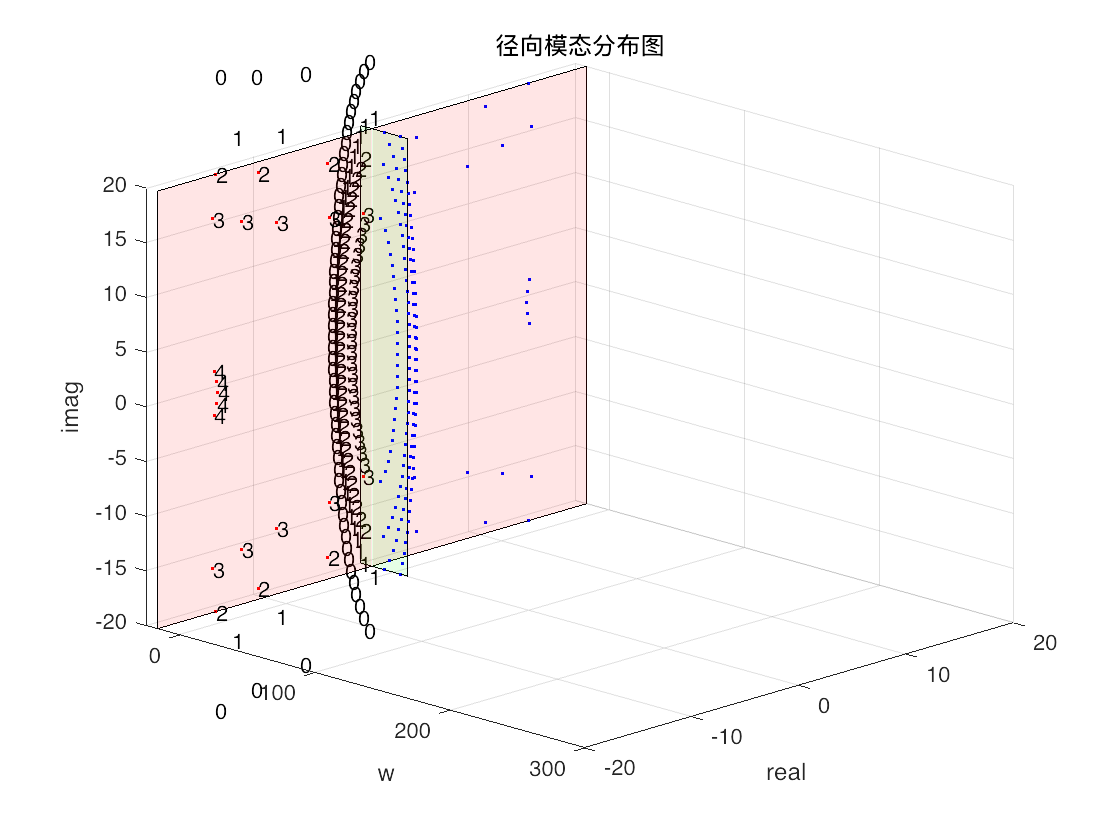

EigValue_left=cell2mat(initialEigValue_left.');EigValue_right=cell2mat(initialEigValue_right.');
Mode_enlarge_left=cell2mat(mode_enlarge_left.');Mode_enlarge_right=cell2mat(mode_enlarge_right.');
Len_left=cell2mat(len_left);Len_right=cell2mat(len_right);

figure;plot3(real(EigValue_left),imag(EigValue_left),Mode_enlarge_left,'.r');hold on;plot3(real(EigValue_right),imag(EigValue_right),Mode_enlarge_right,'.b');
view([0 0]);
text(real(EigValue_left),imag(EigValue_left),Mode_enlarge_left,num2str(Len_left'));
%text(real(EigValue_right),imag(EigValue_right),Mode_enlarge_left,num2str(Len_right'));
grid on;
para.TPP1=fill3([cutOffLine cutOffLine cutOffLine  cutOffLine],[-20 -20 20 20],[-20 20 20 -20],'r','FaceAlpha',0.1); %添加颜色        % handle !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
set(para.TPP1,'Visible','on')  
para.TPP2=fill3([10 -25 -25 10],[0 0 0 0],[-20 -20 20  20],'g','FaceAlpha',0.1); %添加颜色        % handle !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
set(para.TPP2,'Visible','on') 

view([43.1 -4.3])

xlim([-25 300])
ylim([-20.0 20.0])
zlim([-20.0 20.0])
view([44.4 21.8])
title('径向模态分布图')
xlabel('w')
zlabel('imag')
ylabel('real')

整理模态信息：

数组为n列，周向模态m从-(n-1)/2:(n-1)/2依此给出

         0. mode_enlarge: 周向模态；

- mode1:序列号--》可以找到对应的特征函数；

- initialEigValue:特征值,区分上下游；

- len1：径向模态；区分上下游；

- LEFT 为上游；RIGHT为下游；

Info=[mode_enlarge;mode1;initialEigValue;initialEigValue_left;initialEigValue_right;len1;len_left;len_right]

Info = 8×81 cell 数组
    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {0×1 double}    {2×1 double          }    {2×1 double          }    {2×1 double          }    {2×1 double          }    {2×1 double          }    {2×1 double          }    {4×1 double   }    {4×1 double   }    {4×1 double   }    {6×1 double         }    {6×1 double         }    {6×1 double         }    {6×1 double         }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {8×1 double               }    {10×1 double                    }    {10×1 double    

上述代码通过求矩阵的特征值，可以分析管道声场的传播性质。区分上下游，有部分被截止，有部分传播。

每个点都代表单一的模态。V代表特征函数，[U,V,W,P,S]五个参数组成；

比如，要画出周向模态为-14， 上游，序列号为83; 进一步可以继续扩展到面，不再赘述。

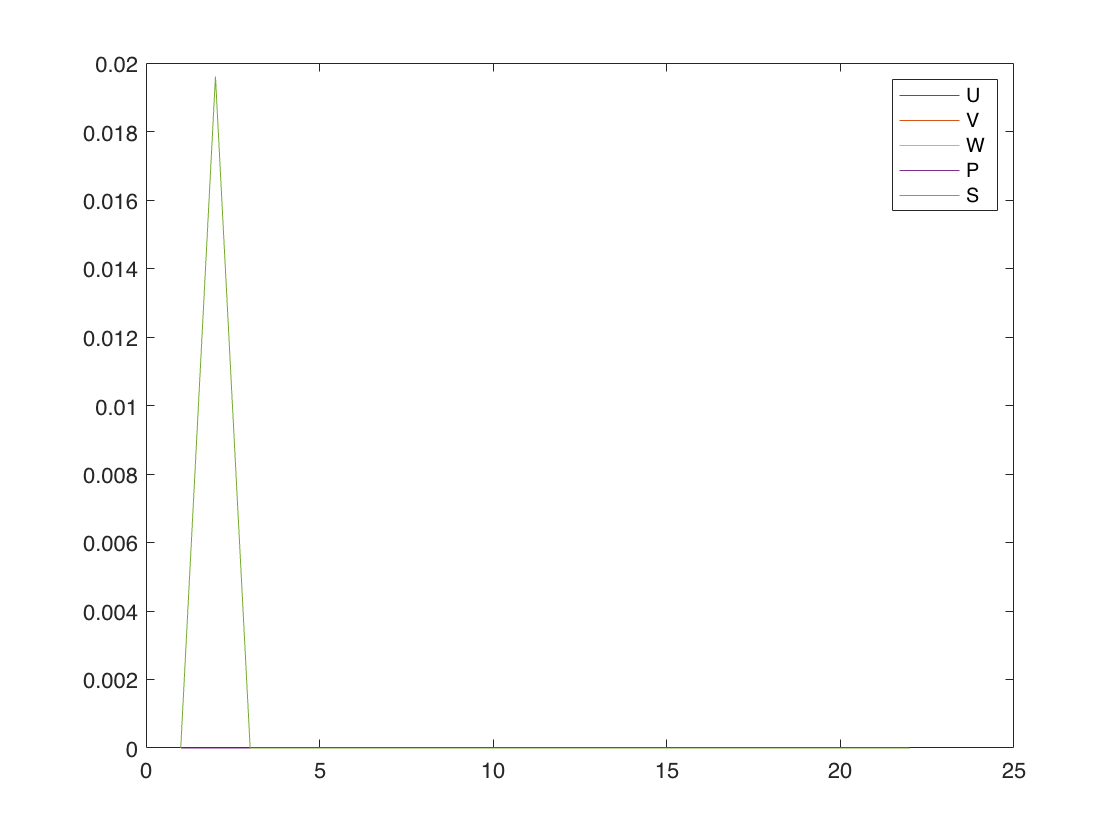

figure;
plot(real(V{1,3}{2}).')
legend({'U','V','W','P','S'})

接下来，是计算格林公式。

首先给定一些离散化的参数

%% ----------重建面------------------------------------------
i_r=30;i_cirshift=25;i_equal=16;i_theta=i_equal*i_cirshift;%16个等间隔传感器，因此为16的整数倍，方便累加，无需差值
theta2=(0:i_theta-1)*(360/i_theta);
xr2=linspace(Ratio*rT,rT,i_r);%不沾边，防止Gnm为NA
xr=xr2'*cos(theta2*pi/180);yr=xr2'*sin(theta2*pi/180);%Xnet
zr=0*repmat(1,size(xr));
Angle=90;%偶极子声源的方向；90度对应实验
zH = [-0.3];                 %测量距离
r_pole=linspace(Ratio,1,i_r);%脉冲点位一列
x_pole=zH/rT;



上下游选择问题：

如果是上游-，选择LEFT；如果是下游+，选择RIGHT；

x_pole=0.001; 
Mode_enlarge1=Mode_enlarge_right; %选择上游或者下游
EigValue1=EigValue_right;  %特征值
initialEigValue1=initialEigValue_right;

计算重建面上的离散的格林公式：

实际上，为了beforming的需求，我们格林函数已经完成了i_r个不同r位置的全部计算（矩阵计算，效率非常高！）。同时也完成了周向的计算。

因此，最终我们得到的矩阵为：

- Tm/Gm：Inf*i_r

- Tv/Gv：i_r*i_theta

- Amp_Tm/Amp_Gm：i_r*1

Nice！（as well，非常喜欢matlab的实时编辑器环境！）

%Gv和Tv是Gm和Tm的离散形式
Tm=[];Tv=[];Gm=[];Gv=[];Amp_Tm=[];Amp_TG=[];
for nk=1:length(Mode_enlarge_left)%可以并向
    [Tm{nk,1},Tv{1,nk},Gm{nk,1},Gv{1,nk},Amp_Tm{1,nk},Amp_Gm{1,nk}]=greenfun_dipole_initial(Boundary,Mode_enlarge1(nk),Ratio,w,Tr,Omag,Mx,c02,rou0,EigValue1(nk),z_t,z_h,r_pole,x_pole,i_r,i_theta,Angle,0);%算green函数（1*length(x_pole) cell）
end  

开始计算。。。m=-29  w=25  upstram/downstream   mode:  -16.6667+14.5743i
该计算完成。m=-29  w=25  upstram/downstream   mode:  -16.6667+14.5743i
开始计算。。。m=-28  w=25  upstram/downstream   mode:  -16.6667+11.2869i
该计算完成。m=-28  w=25  upstram/downstream   mode:  -16.6667+11.2869i
开始计算。。。m=-27  w=25  upstram/downstream   mode:  -16.6667+6.7192i
该计算完成。m=-27  w=25  upstram/downstream   mode:  -16.6667+6.7192i
开始计算。。。m=-26  w=25  upstram/downstream   mode:  -10.8076+2.14362e-12i
该计算完成。m=-26  w=25  upstram/downstream   mode:  -10.8076+2.14362e-12i
开始计算。。。m=-25  w=25  upstram/downstream   mode:  -6.1294+7.9514e-13i
该计算完成。m=-25  w=25  upstram/downstream   mode:  -6.1294+7.9514e-13i
开始计算。。。m=-24  w=25  upstram/downstream   mode:  -3.0666-4.7073e-14i
该计算完成。m=-24  w=25  upstram/downstream   mode:  -3.0666-4.7073e-14i
开始计算。。。m=-23  w=25  upstram/downstream   mode:  -16.6667+13.0436i
该计算完成。m=-23  w=25  upstram/downstream   mode:  -16.6667+13.0436i
开始计算。。。m=-23  w=25  upstram/downstream   mode:  -0.66312+2.5091e-13i


% 找到一处bug，周向模态的顺序会由于空集和同一个模态有多个周向模态而发生改变。因此，我们需要对其进行重新组合。

% TODO: 上下游测试。

k=1;Tm1=[];Gm1=[];Tv1=[];Gv1=[];Amp_Tm1=[];Amp_Gm1=[];
for km=1:length(mode) %周向序列循环
    for kn=1:length(initialEigValue1{km})             %径向序列循环
            Tm1{kn,km}=Tm{k,1};
            Gm1{kn,km}=Gm{k,1};
            Tv1{kn,km}=Tv{1,k};
            Gv1{kn,km}=Gv{1,k};
            Amp_Tm1{kn,km}=Amp_Tm{1,k};
            Amp_Gm1{kn,km}=Amp_Gm{1,k};
            k=k+1;    
    end
end

% 补充为覆盖的区域
kn=size(Tm1,1);
Tm1{kn,km}=[];
Gm1{kn,km}=[];
Tv1{kn,km}=[];
Gv1{kn,km}=[];
Amp_Tm1{kn,km}=[];
Amp_Gm1{kn,km}=[];



作图，验证模态能量分布：

首先，我们需要对相同能量位置的进行累加操作：

Amp_Tm2=[];Amp_Gm2=[];
for km=1:length(mode)
    Amp_Tm2{km}=zeros(i_r,1);
    Amp_Gm2{km}=zeros(i_r,1);
    for kn=1:size(Amp_Tm1,1)
        if isempty(Amp_Tm1{kn,km})
            Amp_Tm1{kn,km}=zeros(i_r,1);
            Amp_Gm1{kn,km}=zeros(i_r,1);
        end
        Amp_Tm2{km}=Amp_Tm2{km}+Amp_Tm1{kn,km};
        Amp_Gm2{km}=Amp_Gm2{km}+Amp_Gm1{kn,km};
    end
end
Amp_Tm3=cell2mat(Amp_Tm2);
Amp_Gm3=cell2mat(Amp_Gm2);


for ir=1:i_r
    Tv2{ir,1}=zeros(i_r,i_theta);
    Gv2{ir,1}=zeros(i_r,i_theta);
end

for km=1:length(mode)
    for kn=1:size(Amp_Tm1,1)
        for ir=1:i_r
            if isempty(Tv1{kn, km})
            else
                Tv2{ir,1}=Tv2{ir,1}+Tv1{kn, km}{ir,1};
                Gv2{ir,1}=Gv2{ir,1}+Gv1{kn, km}{ir,1};
            end
        end
    end
end

ir = 15;    %代表不同的半径位置的声源特性 
mmode = 15;   %周向模态
nnode = 1;   %径向模态

开始画图：

周向模态的能量分布图（不同ir）

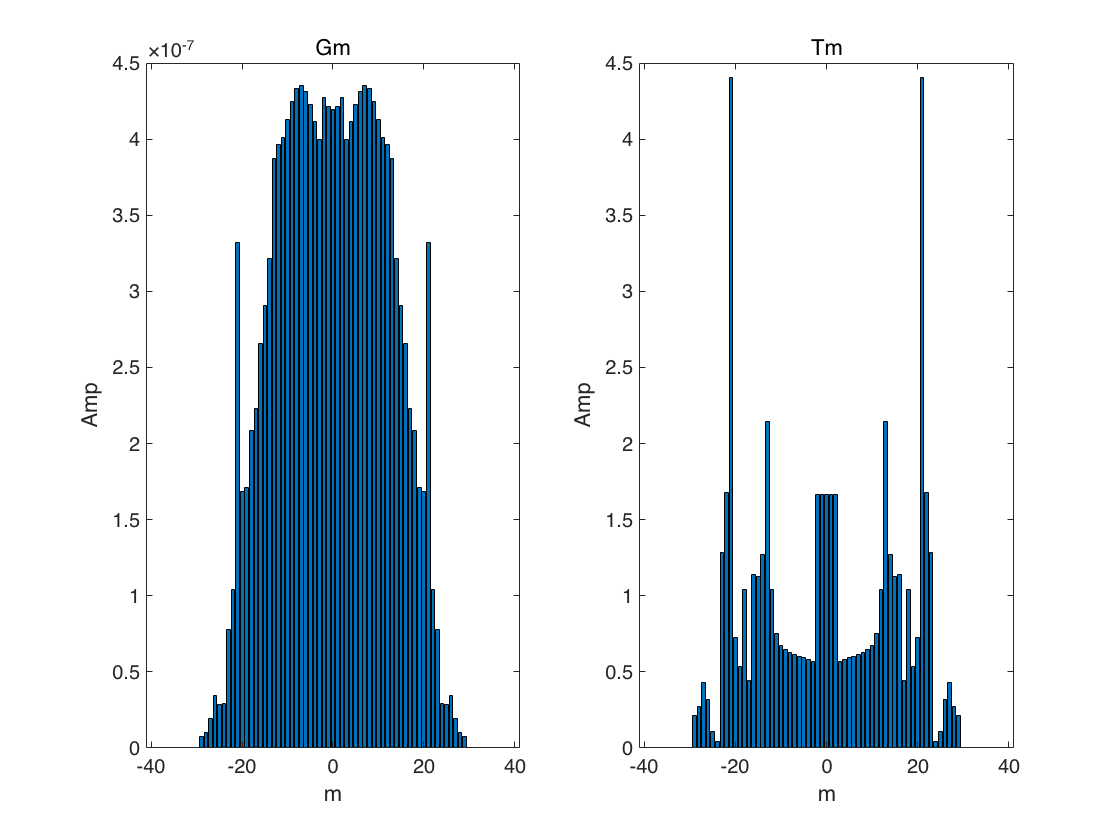


figure
subplot(1,2,1)

bar(mode,Amp_Gm3(ir,:));%
xlabel('m')
ylabel('Amp')
title('Gm')
subplot(1,2,2)
bar(mode,Amp_Tm3(ir,:));%
xlabel('m')
ylabel('Amp')
title('Tm')

现在，来画模态为m=15；n=0的周向图

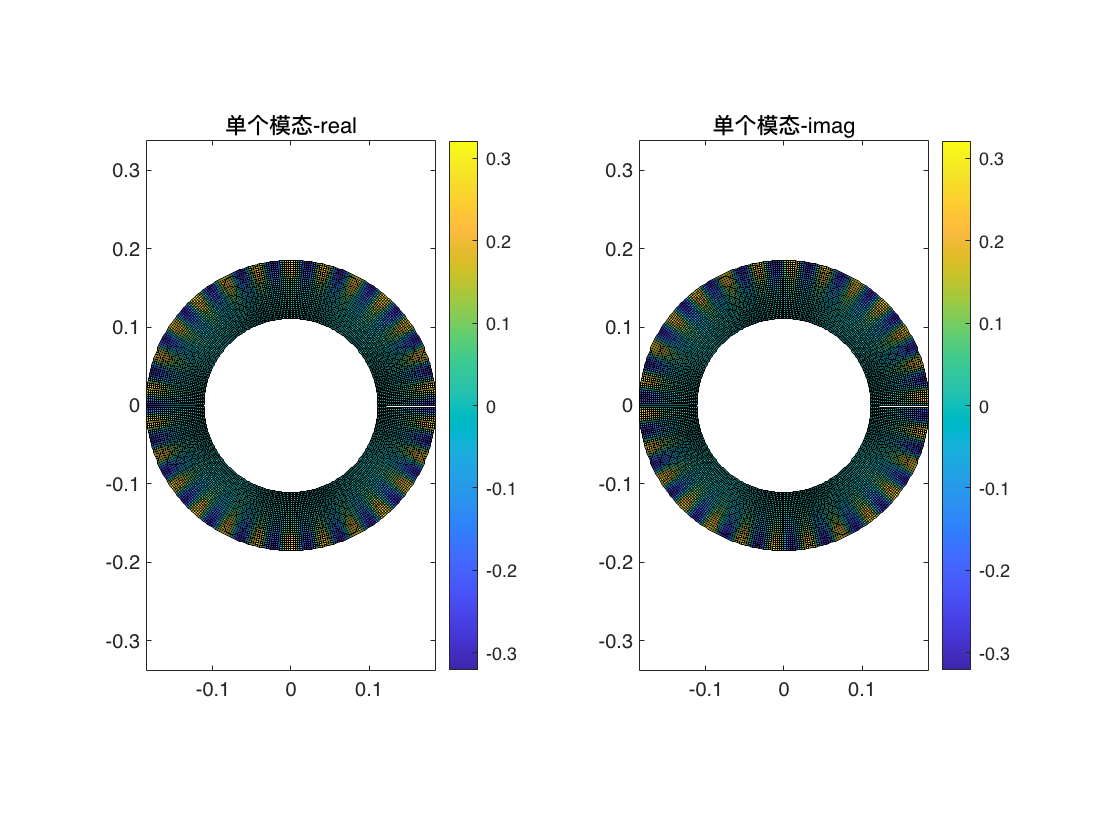


xr=xr2'*cos(theta2*pi/180);yr=xr2'*sin(theta2*pi/180);%Xnet
h1=figure;
subplot(1,2,1)
Qref = real(Tv1{nnode,mmode}{ir,1}); %不同ir点
h1 = pcolor(xr,yr,Qref);% plot in dB unit,
axis equal
colorbar
title('单个模态-real')
subplot(1,2,2)
Qref = imag(Tv1{nnode,mmode}{ir,1}); %不同ir点
h1 = pcolor(xr,yr,Qref);% plot in dB unit,
axis equal
title('单个模态-imag')

colorbar

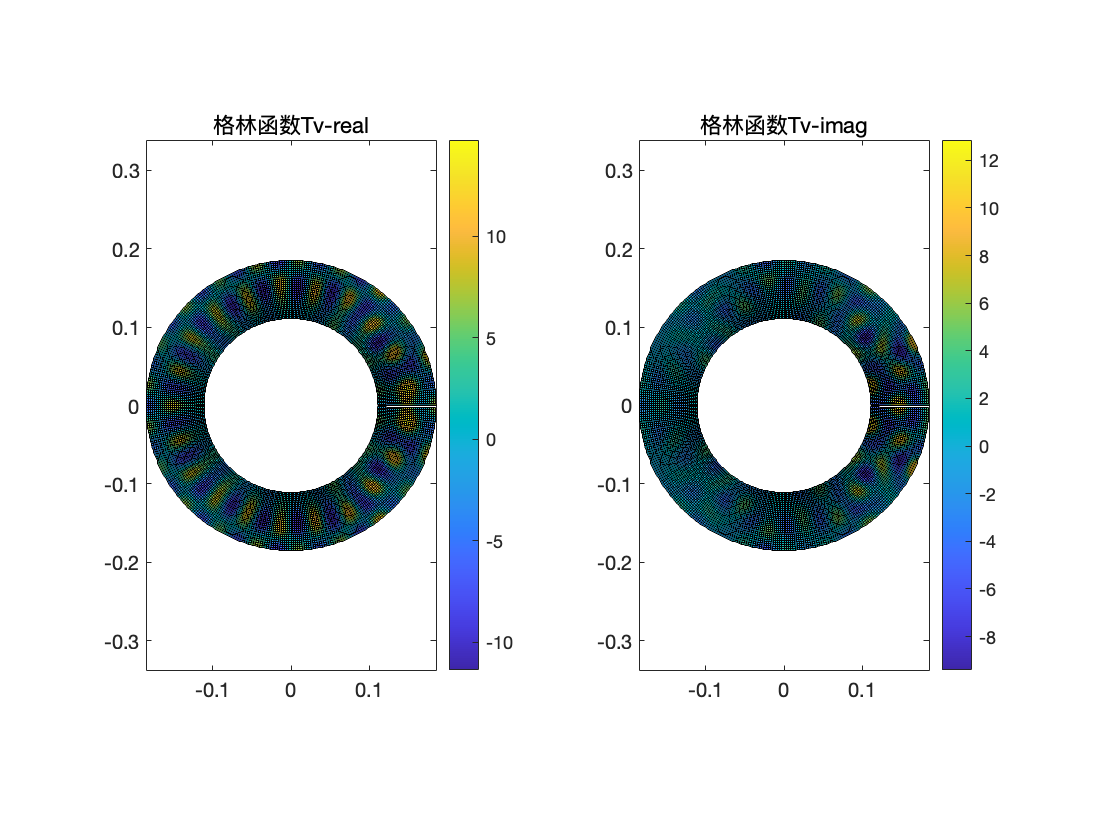

h2=figure;
subplot(1,2,1)
Qref = real(Tv2{ir,1}); %不同ir点
h1 = pcolor(xr,yr,Qref);% plot in dB unit,
axis equal
colorbar
title('格林函数Tv-real')
subplot(1,2,2)
Qref = imag(Tv2{ir,1}); %不同ir点
h1 = pcolor(xr,yr,Qref);% plot in dB unit,
axis equal
title('格林函数Tv-imag')

colorbar

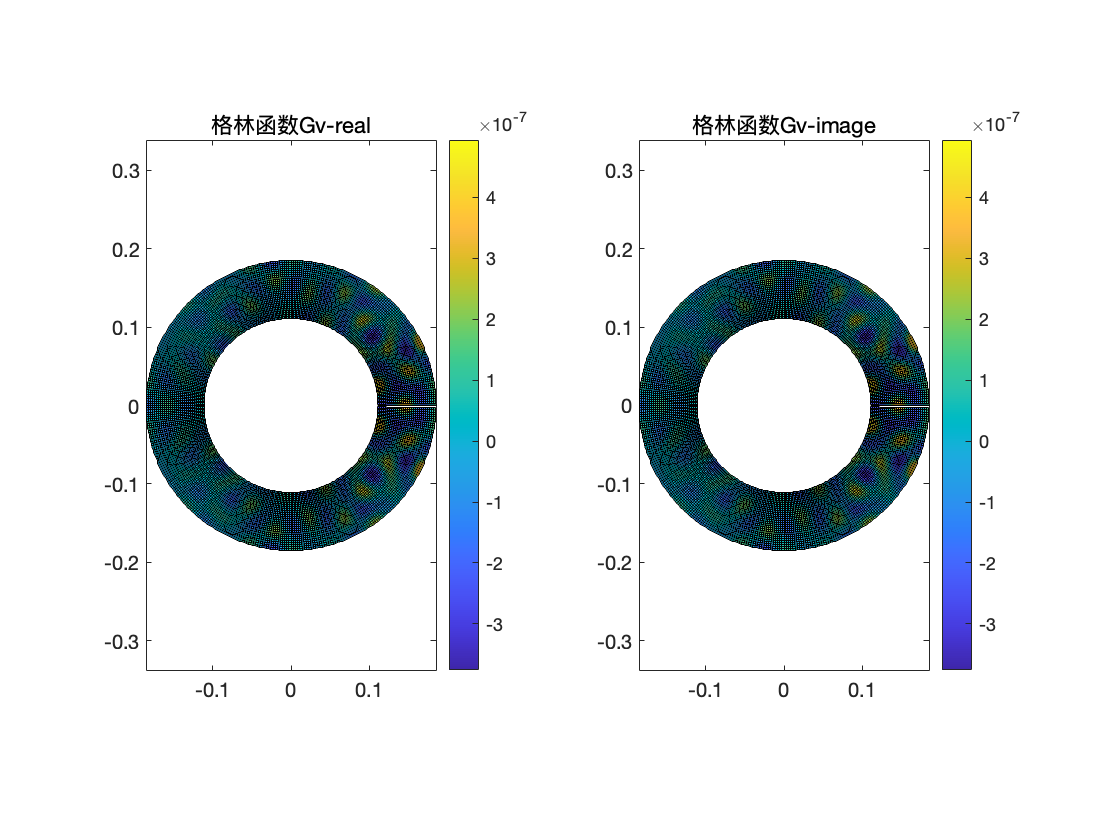

h3=figure;
subplot(1,2,1)
Qref1 = real(Gv2{ir,1}); %不同ir点
h1 = pcolor(xr,yr,Qref1);% plot in dB unit,
axis equal
colorbar
title('格林函数Gv-real')
subplot(1,2,2)
Qref1 = real(Gv2{ir,1}); %不同ir点
h1 = pcolor(xr,yr,Qref1);% plot in dB unit,
axis equal
title('格林函数Gv-image')
colorbar

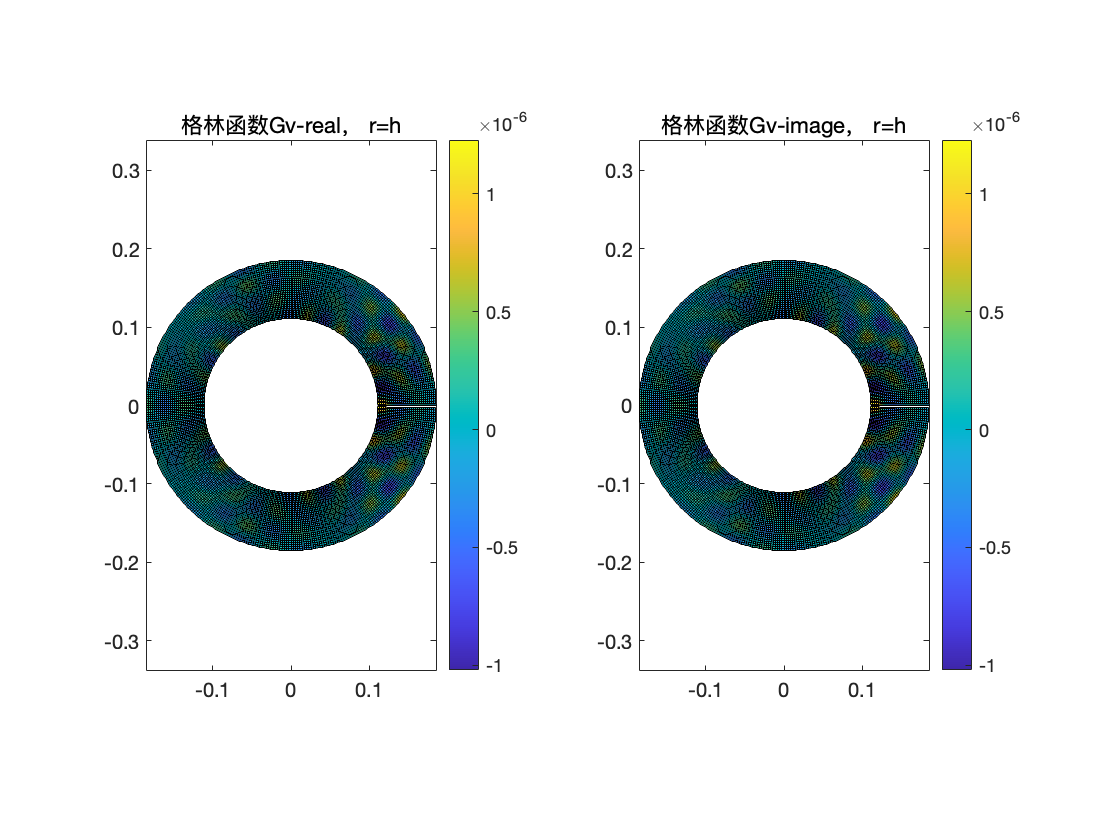

h3=figure;
subplot(1,2,1)
Qref1 = real(Gv2{1,1}); %不同ir点
h1 = pcolor(xr,yr,Qref1);% plot in dB unit,
axis equal
colorbar
title('格林函数Gv-real， r=h')
subplot(1,2,2)
Qref1 = real(Gv2{1,1}); %不同ir点
h1 = pcolor(xr,yr,Qref1);% plot in dB unit,
axis equal
title('格林函数Gv-image， r=h')
colorbar

验证以前的结果：结果验证成功！

单可以看出，即使是离声源面非常近的场，其旁瓣的影响依然非常的严重！(更好的近似需要更多的模态进行累加才行。)这可能是导致实际做波束形成结果不准确的原因。

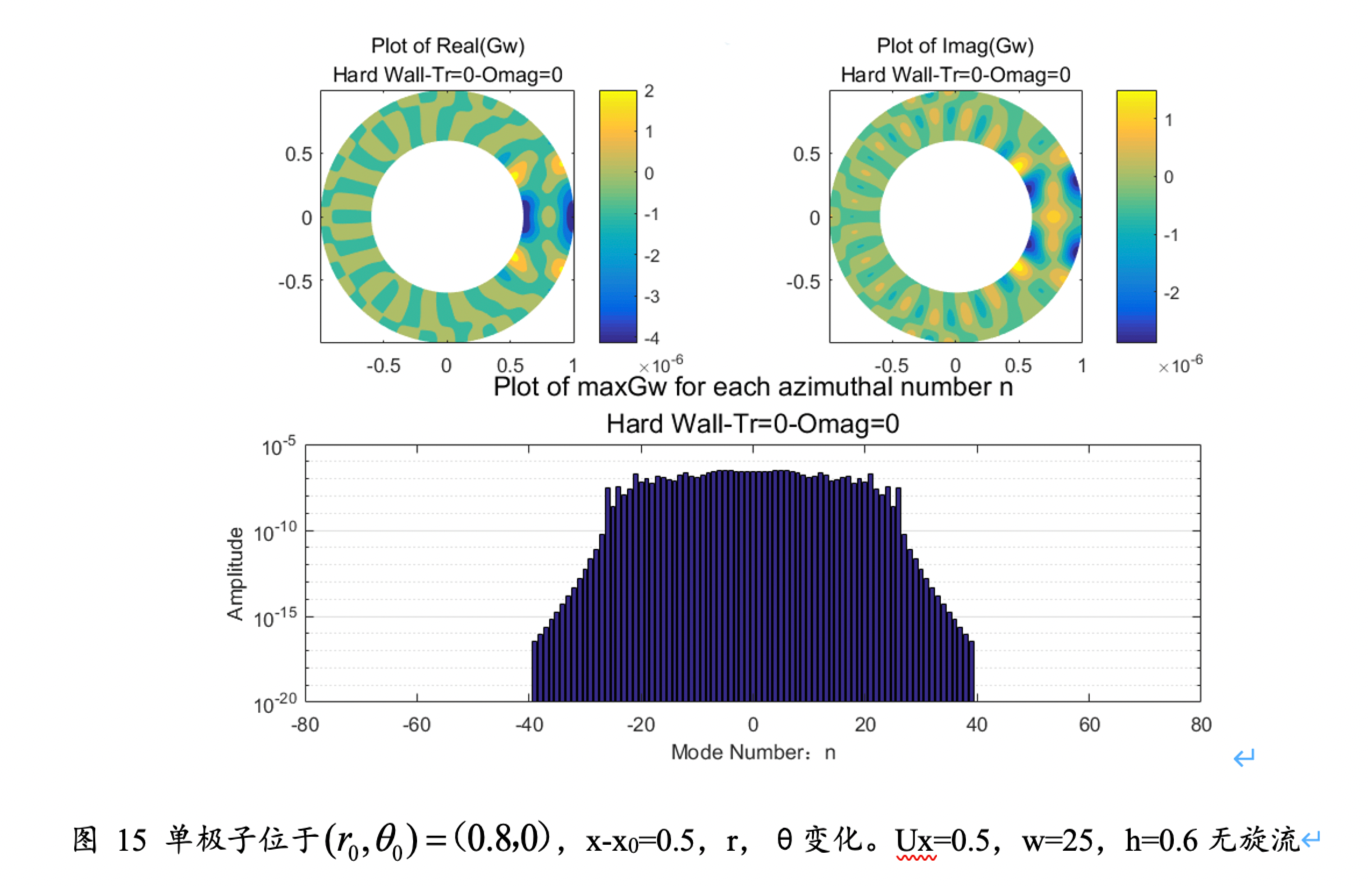

接下里，累加生出单极子和偶极子声源

max(Qref)

ans =    12.4464   12.0312   10.8291    8.9649    6.6306    5.0591    5.1966    5.2741    6.3554    8.2665    9.9530   11.3193   12.2858   12.7944   12.8125   12.3368   11.3936   10.0381    8.5987    8.2190    7.2512    5.9775    4.5810    3.3568    5.4536    7.9637   10.0263   11.4033   11.9367   11.5707   10.3606    8.4652    6.1353    6.6859    6.8906    6.7453    6.3061    6.0308    6.3768    6.4847    6.3875    6.1305    5.7649    5.3409    4.9025    4.4827    4.1008    3.7616    3.4563    3.1655
